# Bayesian learning models

This script gives an overview of how Bayesian learning models work and their advantages over classic reinforcement learning

## Classic reversal learning problem

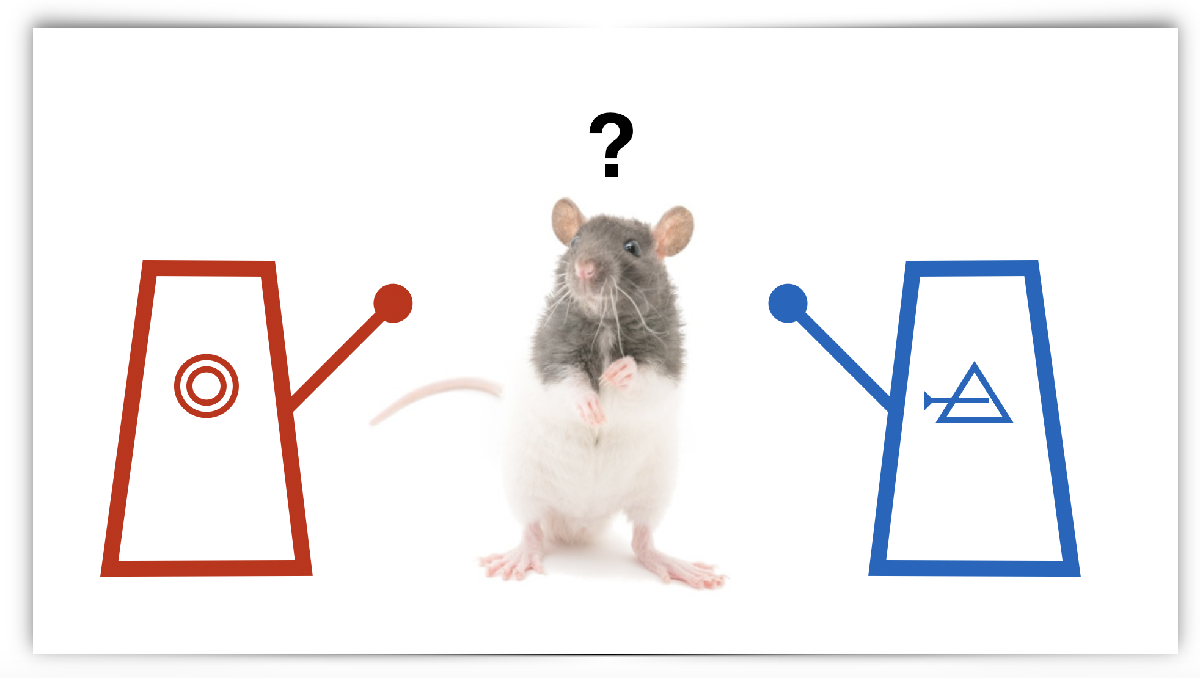

A rat is in a cage with two levers.

On each trial, a food pellet is hidden in either the red box, or the blue box. If the rat presses the lever on the correct box, it gets the food.

The probability that the red box contains the food is initially 80% (probability for the blue box is therefore 20%) but after a while the probabilities reverse

The rat must therefore keep learning about which is the high probability box.

## Simulation of the task

Let's simulate what the experimenter decided (pRed - the probability that the reward is in the red box) and what the rat sees (rewardsRed - a vector which has a 1 if the reward was in the red box and a 0 if it was in the blue box)

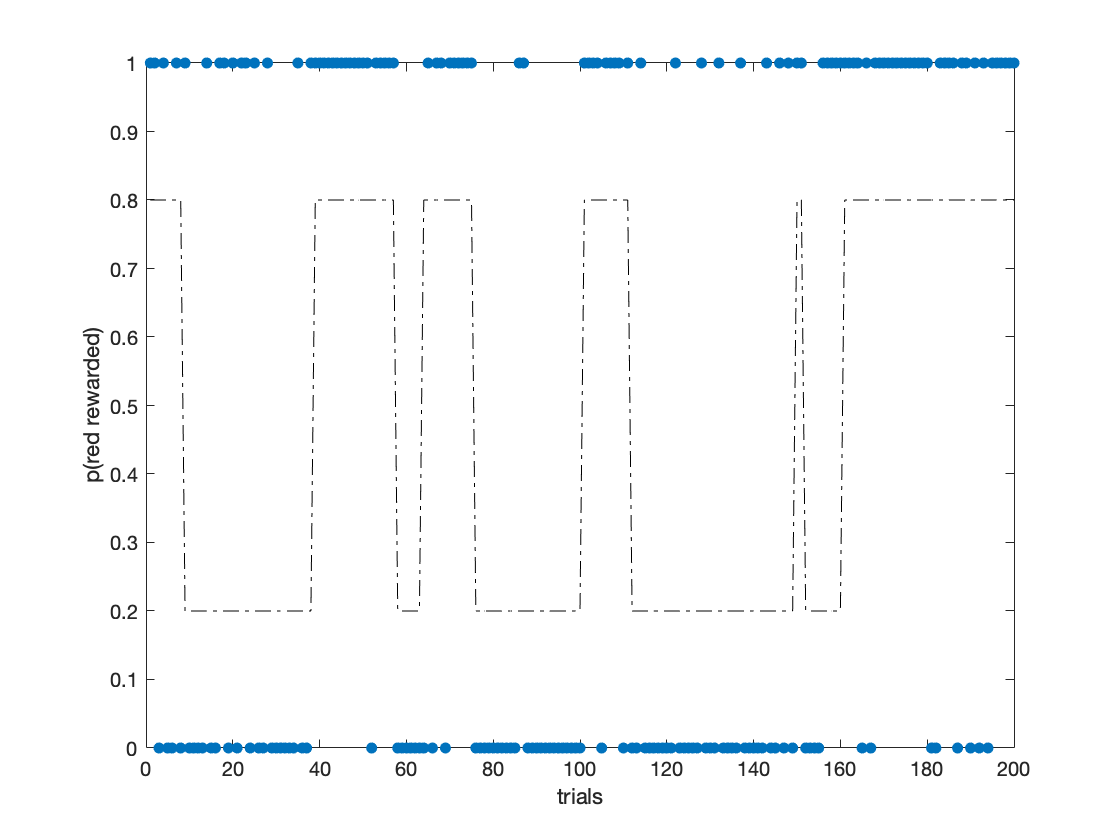

clear; close all; %fresh start

nTrials = 200;
pRed = NaN(nTrials,1);
pRed(1) = 0.8;

% generate schedule
for t=2:nTrials
    if rand<1/15 
        pRed(t)=1-pRed(t-1) ;
    else
        pRed(t) = pRed(t-1) ;
    end
end

% work our whether red was rewarded on each trial (red reward coded as 1, bblue reward coded as 0)
rewardsRed = rand(size(pRed))<pRed;

figure;
plot(pRed,'k-.'); hold on;
plot(rewardsRed,'.','MarkerSize',15)
xlabel('trials'); ylabel('p(red rewarded)')

## Modelling the rat's beliefs

The rat should choose the box with the higher probability of containing the reward but it cannot directly observe pRed(t). It has to estimate pRed(t) from its past observations rewardsRed(1:t-1).

## Reinforcement learning

The classic solution is to use a reinforcement learning algorithm such as Rescorla-Wagner or temporal difference learning

% implement Rescorla-Wagner learning for the simluated experiment

V = NaN(nTrials,1); %V is the 'value' or expected reward of the red box
V(1) = 0.5;
alpha = 0.2;

for t=2:nTrials
    V(t) = V(t-1) + alpha*(rewardsRed(t-1)-V(t-1)); %Rescorla-Wagner equation
end

hold on;
plot(V,'r')

The red line tracks what the rat should believe is  the probability of the reward falling in the red box (according to the model).

The red 'belief' line lags the black dashed 'ground truth' line as the rat needs so see a few outcomes to notice when a reversal occurs - that makes sense.

*Aside on learning rate:*

- *We had to choose the learning rate, alpha, which is aribtrarily set to 0.1. *

- *Try changing alpha and seeing how it affects the lag of the red 'belief' line behind the 'ground truth' black line- values should lie between 0 (no learning) and 1 (complete update on each trial)*

- *You should notice that for low values of alpha, learning is very slow, whilst for high values, it is too jumpy and fails to integrate evidence across multiple trials*

- *What if you set alpha outside the range [0,1]?*

- *There is a Bayesian solution to setting the learning rate as explained in *[*this paper*](https://pubmed.ncbi.nlm.nih.gov/17676057/)

## Deficiencies of the RL model

**1.  The model does not represent uncertainty.** On each trial we know the rat's best estimate of pRed(t) = V(t). But we cannot distinguish between trials (shortly after a reversal) where he is probably unsure, vs trials (long after a reversal) where he is sure which is the 'good' box. Intuitively, and based on studies described in the lecture, it seems that uncertainty should influence the rat's behaviour and his learning.

**2.  The learning model lacks *****structure*****.** There is no way to build into this model the idea that the rat knows there is always one good box and one bad box, even if it does not know which is which.

Each time there is a reversal, the rat's belief about pRed transitions smoothly from (about) 0.8 to 0.2 or vice versa, passing through intermediate values (at some point, the rat apparently believes the probabilities of reward for red and blue box are 50-50, even though this never really occurs). 

nb. The Rscorla-Wagner model is genius! It was one of the first attempts to quantify a cognitive process and therefore reify the animal's belief state as distinct from its overt behaviour, and generates testable predictions. When I say deficiencies, I'm just pointing out things a Bayesian model can do better, not at all wishing to undermine the importance of this model in the history of psychology, or indeed its current usefulness!

## Representing uncertainty: A Bayesian model

We are now going to write a simpmle Bayesian model of the simulated experiment. Remember the key feature of a Bayesian system is that it calculates the probability that each possible 'ground truth' state is in force, given the observed data.

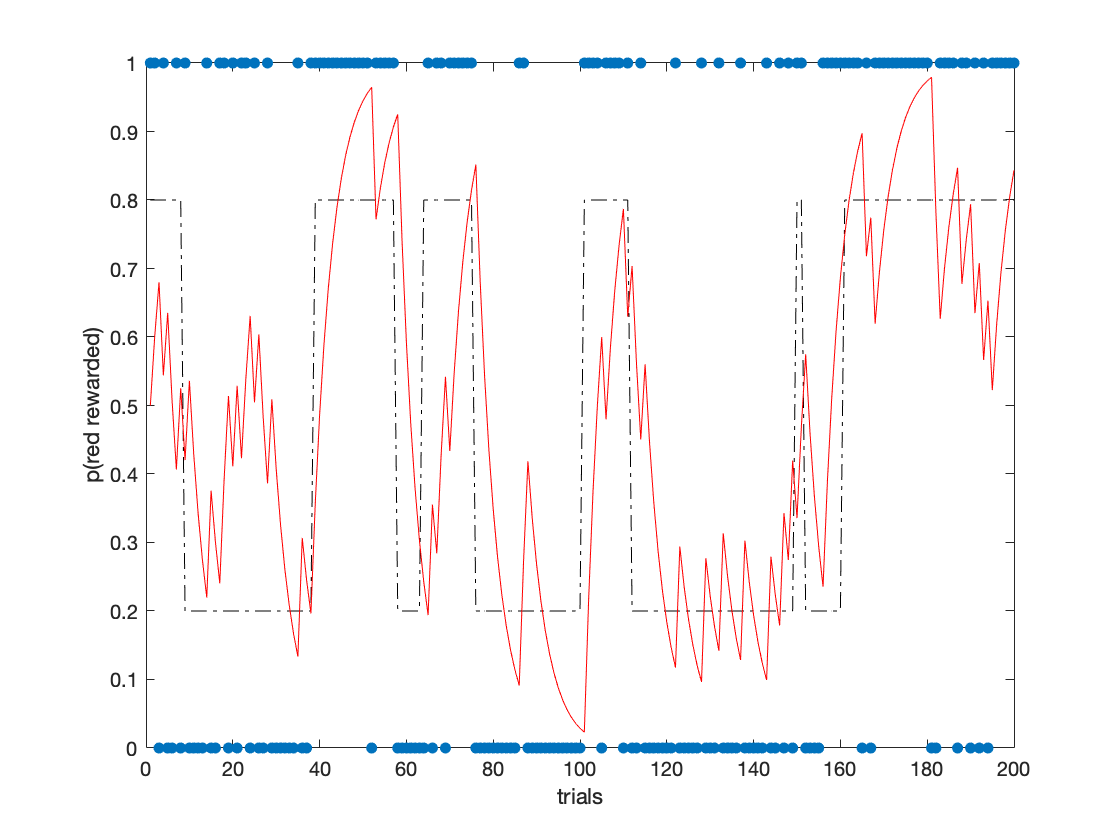

% some possible values for the probability the red box is baited:

pRed_candidateVals = [0.1:0.01:0.99]; 

H = 1/15; % the probability of a reversal on any given trial

% pre-assign some matrices
likelihood = NaN(nTrials,length(pRed_candidateVals));
prior = NaN(nTrials,length(pRed_candidateVals));
posterior = NaN(nTrials,length(pRed_candidateVals));

% set prior on first trial to be the Jeffreys or uniformative prior for a binomial trial
prior(1,:) = betapdf(pRed_candidateVals,0.5,0.5);

% now we do the 'learning' bit:
for t=1:length(rewardsRed)
    % likelihood of candidate values, given the current observation (just this trial)
    if rewardsRed(t)==1
        likelihood(t,:) = pRed_candidateVals; % p(pRed|outcome) = p(outcome|pRed)
    else
        likelihood(t,:) = 1-pRed_candidateVals;
    end
    
    %Bayes theorem <fanfare>
    posterior(t,:) = likelihood(t,:).*prior(t,:); 
    posterior(t,:) = posterior(t,:)./sum(posterior(t,:)); %normalize  - area under curve = 1
    
    % create prior on next trial by incorporating a 'leak'
    prior(t+1,:) = posterior(t,:).*(1-H) + H.*ones(1,size(prior,2))./size(prior,2);
end

***[*Jeffreys prior*](https://en.wikipedia.org/wiki/Jeffreys_prior#Bernoulli_trial)*. A uniform over all candidate values also does a decent job, if less principled!*

## Plotting the model's beliefs

This gives us a posterior 'belief' distribution over candidate values of pRed on each trial. 

Now let's make some plots:

% plot the evoution of the posterior over trials
figure; imagesc(1:nTrials, pRed_candidateVals, posterior'); 
xlabel('trials'); ylabel('pRed');
set(gca,'YDir','normal'); 
caxis([0 0.05]);

% plot ground truth probability as dashed line
hold on;
plot(1:nTrials, pRed,'r-.','LineWidth',2);

Bright colours represent higher posterior probabilities. 

**Expected value of pRed**

If you want to have a single value for the model's belief about the probability the red box is baited, you can use the expected value

% calculated and plot the expected value of pRed: E(X)=sum(X.*p(X))
EV = sum(posterior.*repmat(pRed_candidateVals,nTrials,1),2);
plot(EV,'r-','LineWidth',2);

**Plotting individual trials**

The idea of the posterior as a belief distribution may be clearer if we pick out a couple of individual trials:

for t=[60 80 100] %plot trials 60, 80 and 100 - you can pick some interesting trials from looking at the coloured plot
    figure; plot(pRed_candidateVals, posterior(t,:), 'k');
    xlabel('value of pRed'); ylabel(['posterior probability at trial ' int2str(t)]);
end

- Look at the colourful plot showing the evolution of the posterior and choose some trials where the model is 'certain' or 'uncertain' about the value of pRed

- Modify the code above to plot these individual trials

## Representing structure: another Bayesian model

We observed above that the Rescorla-Wagner learning model lacks *structure*. There is no way to build into this model the idea that the rat knows there is always one good box and one bad box, even if it does not know which is which.

Each time there is a reversal, the rat's belief about pRed transitions smoothly from (about) 0.8 to 0.2 or vice versa, passing through intermediate values (at some point, the rat apparently believes the probabilities of reward for red and blue box are 50-50, even though this never really occurs). 

This is also true for the Baysian model described above. However, we can build a model that does know about this task structure. **Remember the key feature of a Bayesian system is that it calculates the probability that each possible 'ground truth' state is in force, given the observed data. **We get to decide what ground truth states are in the set of candidate options.

How about this?

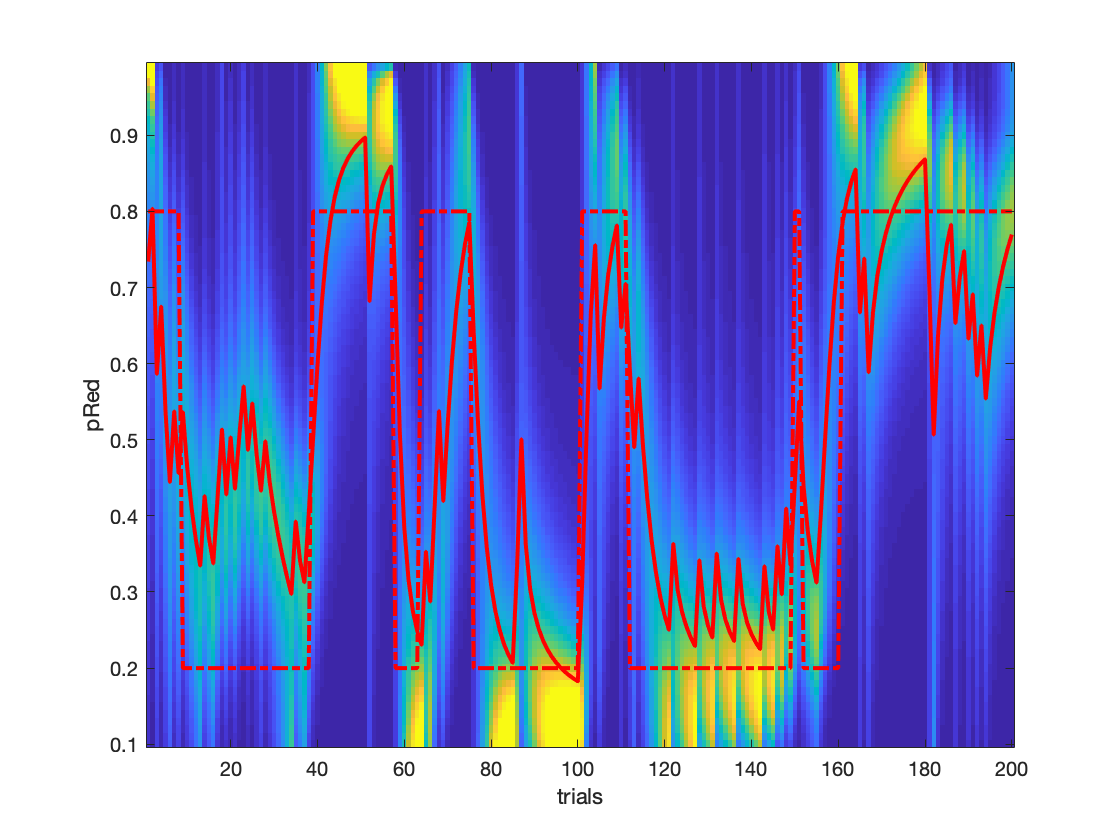

 % some possible values for the probability the red box is baited:
pRed_candidateVals = [0.2 0.8]; 

H = 1/15; % the probability of a reversal on any given trial

% pre-assign some matrices
likelihood = NaN(nTrials,length(pRed_candidateVals));
prior = NaN(nTrials,length(pRed_candidateVals));
posterior = NaN(nTrials,length(pRed_candidateVals));

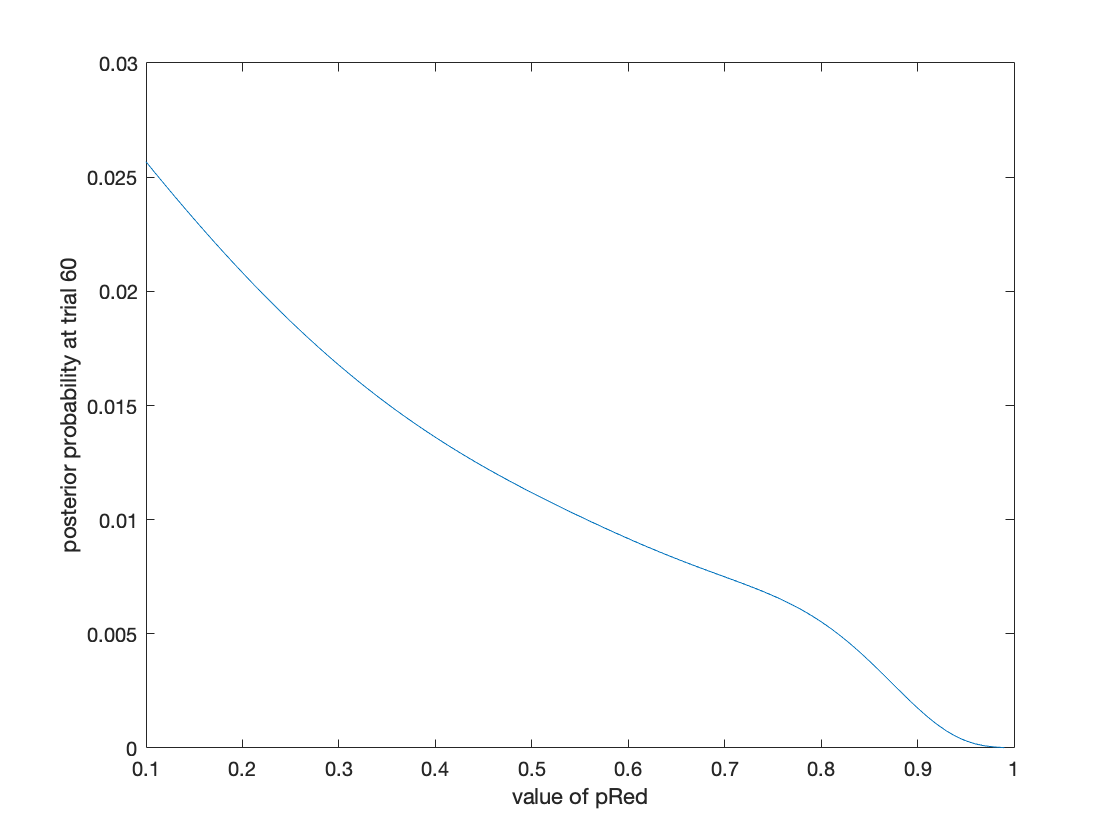

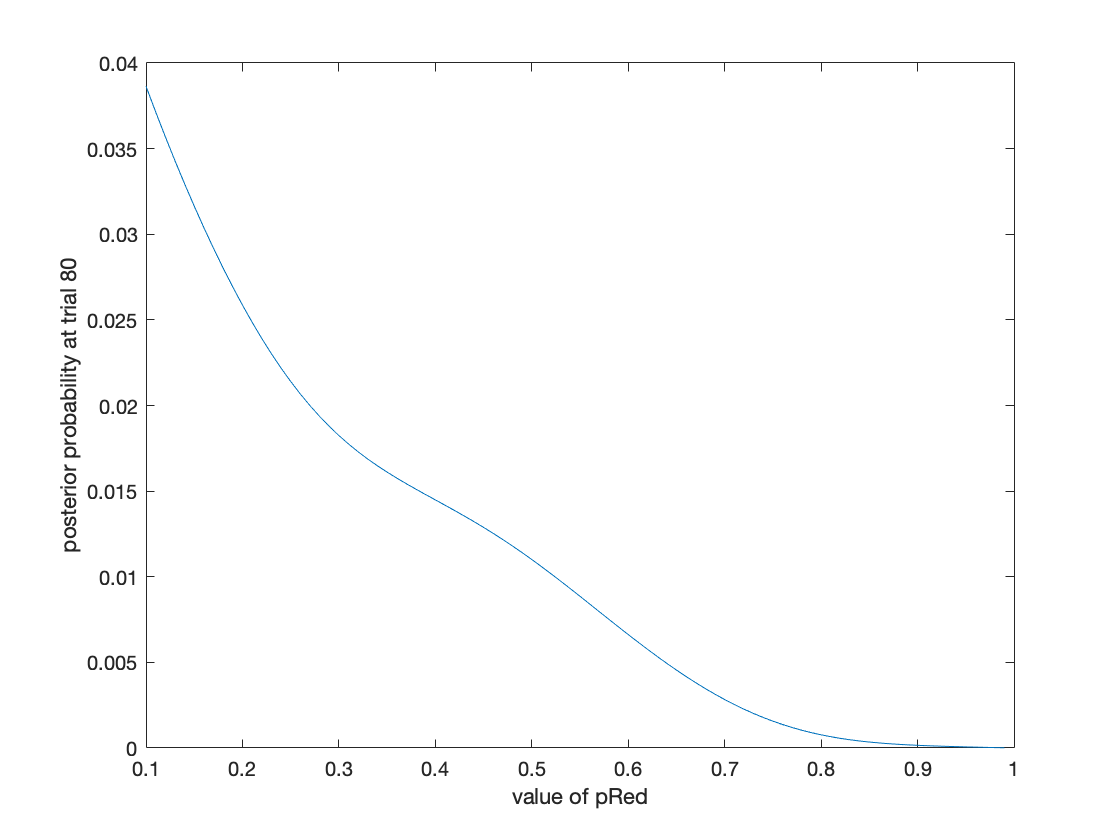

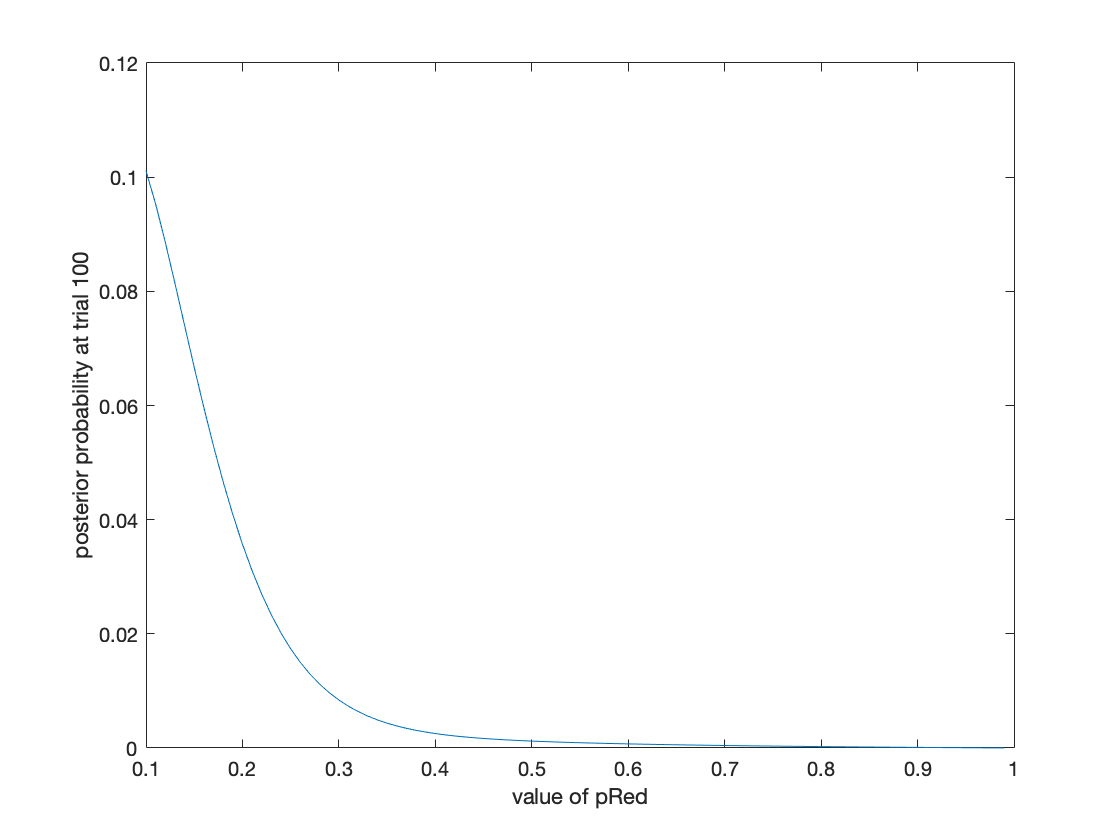


% set prior on first trial to be the Jeffreys or uniformative prior for a binomial trial
prior(1,:) = betapdf(pRed_candidateVals,0.5,0.5);

% now we do the 'learning' bit:
for t=1:length(rewardsRed)
    % likelihood of candidate values, given the current observation (just this trial)

    if rewardsRed(t)==1
        likelihood(t,:) = pRed_candidateVals; % p(pRed|outcome) = p(outcome|pRed)
    else
        likelihood(t,:) = 1-pRed_candidateVals;
    end
    
    %Bayes theorem <fanfare>
    posterior(t,:) = likelihood(t,:).*prior(t,:); 
    posterior(t,:) = posterior(t,:)./sum(posterior(t,:)); %normalize  - area under curve = 1
    
    % create prior on next trial by incorporating a 'leak'
    prior(t+1,:) = posterior(t,:).*(1-H) + H.*ones(1,size(prior,2))./size(prior,2);
end

## Plotting the model's beliefs

This gives us a posterior 'belief' distribution over candidate values of pRed on each trial. 

Now let's make some plots:

% plot the evoution of the posterior over trials
figure; imagesc(1:nTrials, pRed_candidateVals, posterior'); 
xlabel('trials'); ylabel('pRed');
set(gca,'YDir','normal'); 


% plot ground truth probability as dashed line
hold on;
plot(1:nTrials, pRed,'r-.','LineWidth',2); 

**Expected value of pRed**

If you want to have a single value for the model's belief about the probability the red box is baited, you can use the expected value

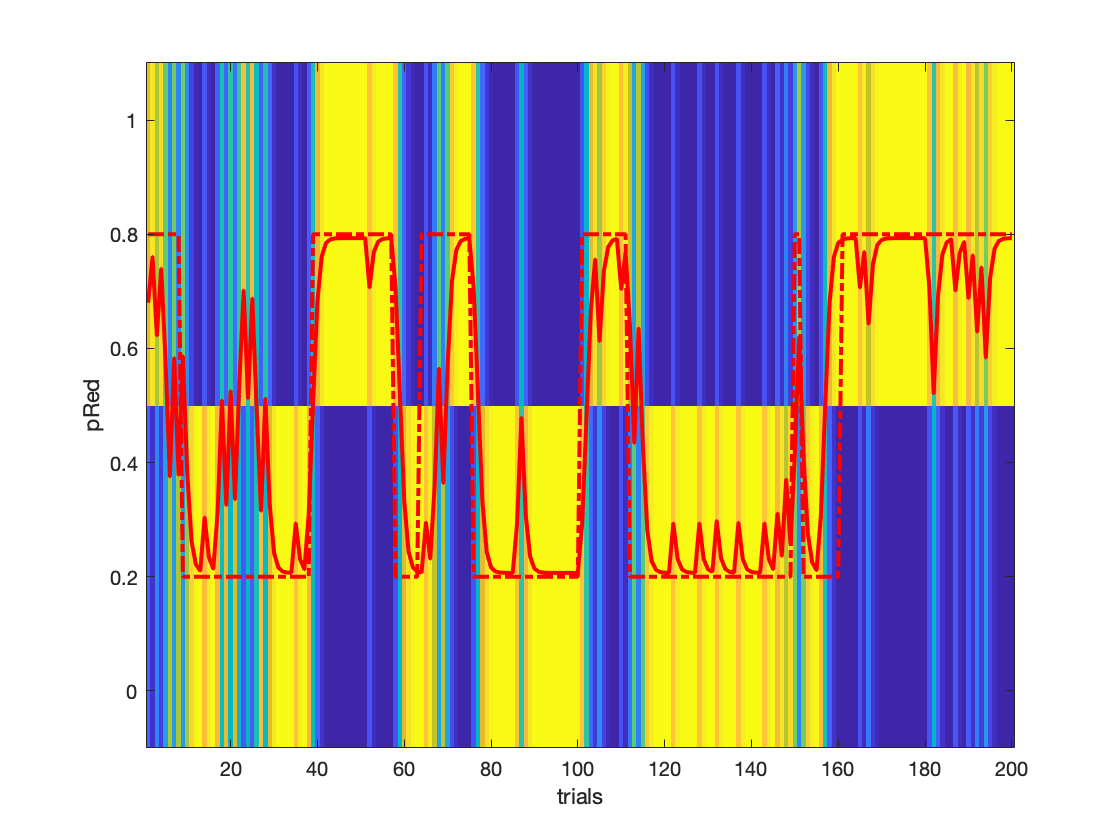

% calculated and plot the expected value of pRed: E(X)=sum(X.*p(X))
EV = sum(posterior.*repmat(pRed_candidateVals,nTrials,1),2);
plot(EV,'r-','LineWidth',2);

Note that this model learns much more quickly about reversals, and does not tend to end up believing in 'intermediate' states like that the red obx is baited 50% of the time (although the expected value of pRed does take intermediate values between 0.2 and 0.8, reflecting uncertainty about which of the two candidate states is in force).

## What is the benefit of building a *structured* model?

Well, the point of building the model is to make a quantitative prediction (or simulation) of how an animal will learn about its environment, given that it mentally represents the structure of the environment in a certain way. 

The animal's mental representation of the environment is sometimes called the **cognitive map.**

We can compare such models using model comparison statistics to determine what structur of model most likely drives an animal;s behaviour, and thus drqaw conclusions about the nature of its cognitive map.

**A more complex cognitive map**

The structure we built in above is simple - does the animal know that the probability red is baited is only ever 20% or 80%? But we could build in more complex structures - does the animal actually know that only one ox is baited (and therefore the proabilities of reward for the two boxes are anti correlated)? In an environment with more options, does it know which sets of options are correlated and which are uncorrelated?

In the real world, atttributes are correlated when they are co-causal - for example, imagine that an alien observes some animals that live inside houses on Earth. Initially she perceives an overwheming variety of small furry creatures, but over time she notices that the values of some attributes predict the values of other attributes - attriubute values are not independent (if the values were numerical rather than categorial we would say the attribubte values are correlated).

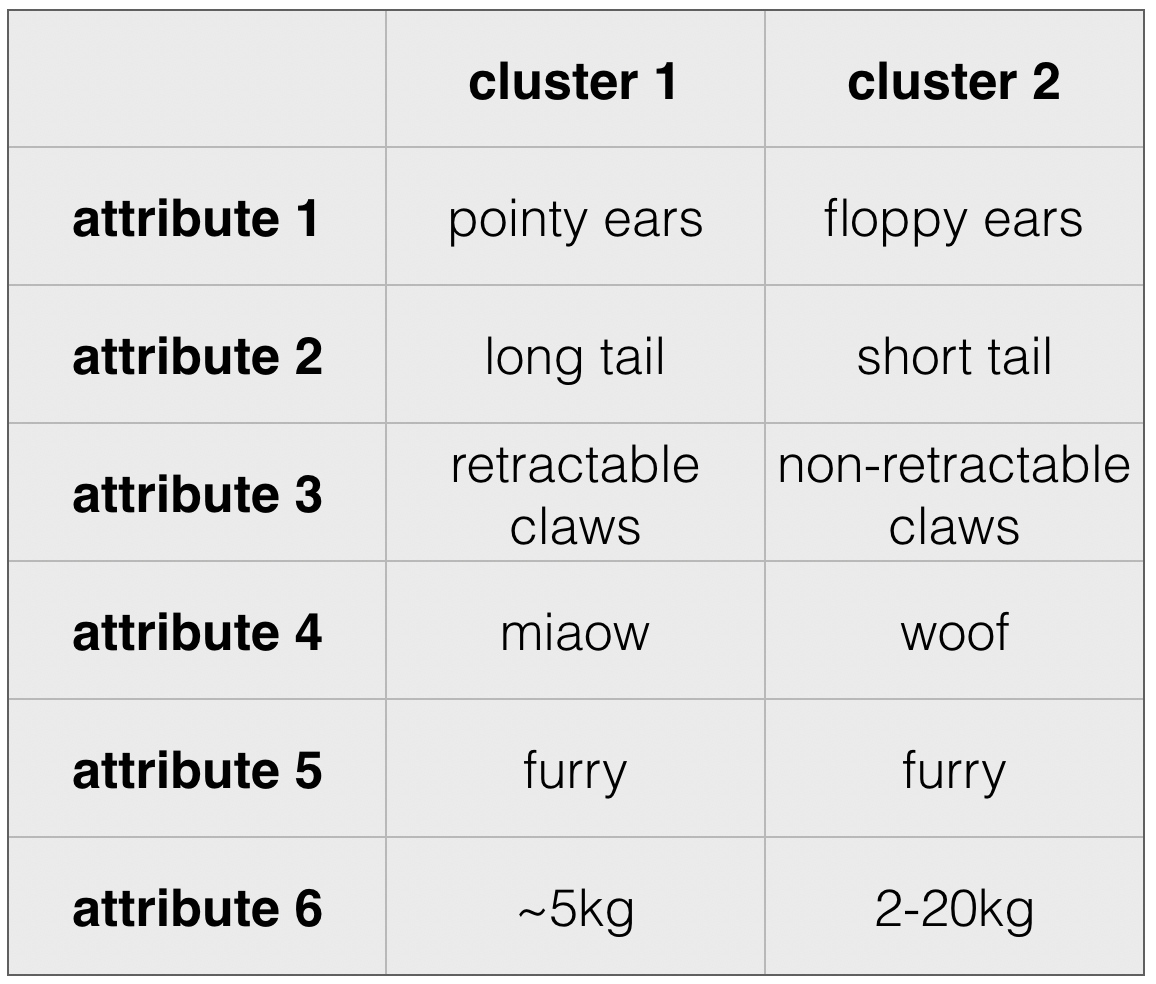 

By noticing the two clusters of attribute values the alien has realised that the animals found inside houses can be grouped into two clusters. 

She also notices that some attributes (5 and 6) are not informmative for determining cluster membership

She now has a cognitive map of house pets that tells us

- how many species of house animal there are (two species covers the clustering well)

- which attributes are most useful and which are less useful for determining species membership

The processes by which observers construct such cognitive maps are of major interest in neuroscience at present.